# CTMC Stochastic SIR Model

Unlike deterministic models, a **stochastic model** is governed by a stochastic element, which can randomly vary as the simulation is run multiple times. In other words, the term **stochasticity** refers to the property of a system in which the randomness of reality is taken into account, as opposed to analogous deterministic systems. Despite the randomness o the results, a precise model may be reached if various simulations are done.

Another characteristic of a stochastic model is that it obeys to the **Markov rule**, which states that the values of the model at the current moment exclusively depend on its values at the previous moment. If the analysed variables take on discrete values, the model can be called a **Markov chain**:

$Prob\{I(t_n+1) | I(t_0), I(t_1), ..., I(t_n)\}=Prob\{I(t_{n+1}) | I(t_n)\}$.

What makes stochastic models advantageous in Epidemiology is that they can predict the dynamics of a disease outbreak in terms of probabilities. For instance, if a large number of simulations give overlapping curves, whereas only few simulations produce other results, the pandemics will likely proceed as those repeating curves suggest.

In a CTMC (Continuous Time Markov Chain) SIS epidemic model, discrete random variables are defined on a continuous time scale where $t=\in[0,\infty)$ and $S(t), I(t) \in \{1,2,...N\}$. In this model, there is only one independent, random variable, $I(t)$, since $S(t)=N-I(t)
$. 

Considering $I(t)= i  \text{ and } I(t+\Delta t)=j, p{_j}{_i} \text{ would be the probability of }i \rightarrow j$. 


$$p{_j}{_i}(t+\Delta t,t)=Prob\{I(t+\Delta t)=j|I(t)=i\}$$


The stochastic SIS model is said to be time homogeneous since the transition probability $p{_j}{_i}(t+\Delta t,t) \text{ does not depend on } t \text{ but only one } \Delta t, p{_j}{_i}(\Delta t). $

The transition probabilities are defined for a small time interval $\Delta t$. These probabilities are refered to as infinitesimal transition probabilities since they are defined for very small $\Delta t$. Therfore the term $o\left(\Delta t\right)$is included in 

$\lim_{t\to 0} \left(o\Delta t/\Delta t\right)=0$.

There are only three possible changes in states since $\Delta t$ is too small:

$i\rightarrow i+1,\text{ }i\rightarrow i-1, \text{ or }i\rightarrow i$.

For each possible transitioin, a probability must be defined, which consist of the rates multiplied by $\Delta t$. 


$$p{_j}{_i}(\Delta t) = 
     \begin{cases}
      \frac{\beta i(N-i)}{N}\Delta t+o(\Delta t),&\quad j=i+1\\
       (b+\gamma)i\Delta t+o(\Delta) t,&\quad j=i-1\\
       1-[\frac{\beta i(N-i)}{N}+(b+\gamma )i]\Delta t+o(\Delta t),&\quad j=i\\
       o(\Delta t),&\quad \text{otherwise}
     \end{cases}$$


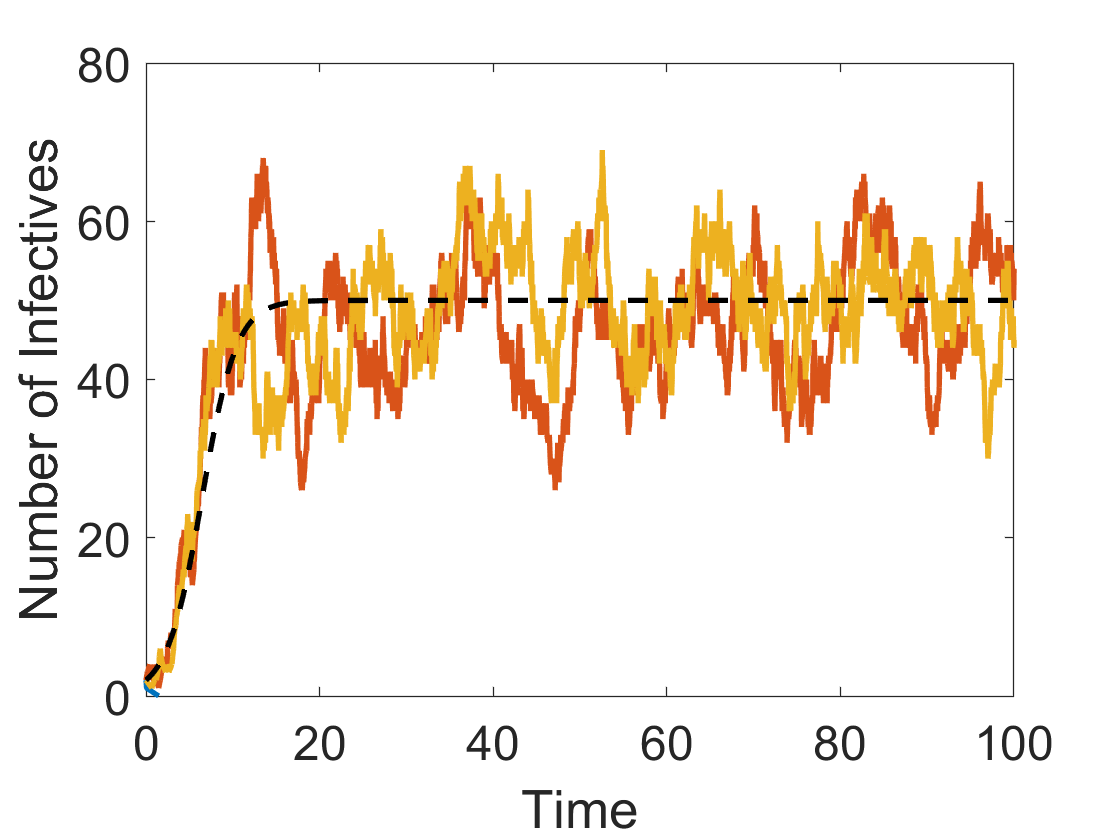

% Matlab Program # 2
% Continuous Time Markov Chain
% SIS Epidemic Model
% Three Sample Paths and the Deterministic Solution
clear
set(0,'DefaultAxesFontSize', 18);
set(gca,'fontsize',18);
beta=1;
b=0.25;
gam=0.25;
N=100;
dt=0.1;
init=2;
time=100;
sim=3;
for k=1:sim
    clear t s i
    t(1)=0;
    i(1)=init;
    s(1)=N-init;
    j=1;
    while i(j)>0 & t(j)<time
        u1=rand; % uniform random number
        u2=rand; % uniform random number
        a=(beta/N)*i(j)*s(j)+(b+gam)*i(j);
        probi=(beta*s(j)/N)/(beta*s(j)/N+b+gam);
        t(j+1)=t(j)-log(u1)/a;
        if u2 <= probi
            i(j+1)=i(j)+1;
            s(j+1)=s(j)-1;
        else
            i(j+1)=i(j)-1;
            s(j+1)=s(j)+1;
        end
        j=j+1;
    end
plot(t,i,'-','LineWidth',2)
hold on
end
% Euler’s method applied to the deterministic SIS model.
y(1)=init;
for k=1:time/dt
    y(k+1)=y(k)+dt*(beta*(N-y(k))*y(k)/N-(b+gam)*y(k));
end
plot([0:dt:time],y,'k--','LineWidth',2);
axis([0,time,0,80]);
xlabel('Time');
ylabel('Number of Infectives');
hold off